# Analise em Laplace

clear all;
close all;
clc;


## Definindo as funções de transferência


Num1 = 1;
Den1 = [1 1];
G1   = tf(Num1,Den1)

G1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



## Respostas temporais

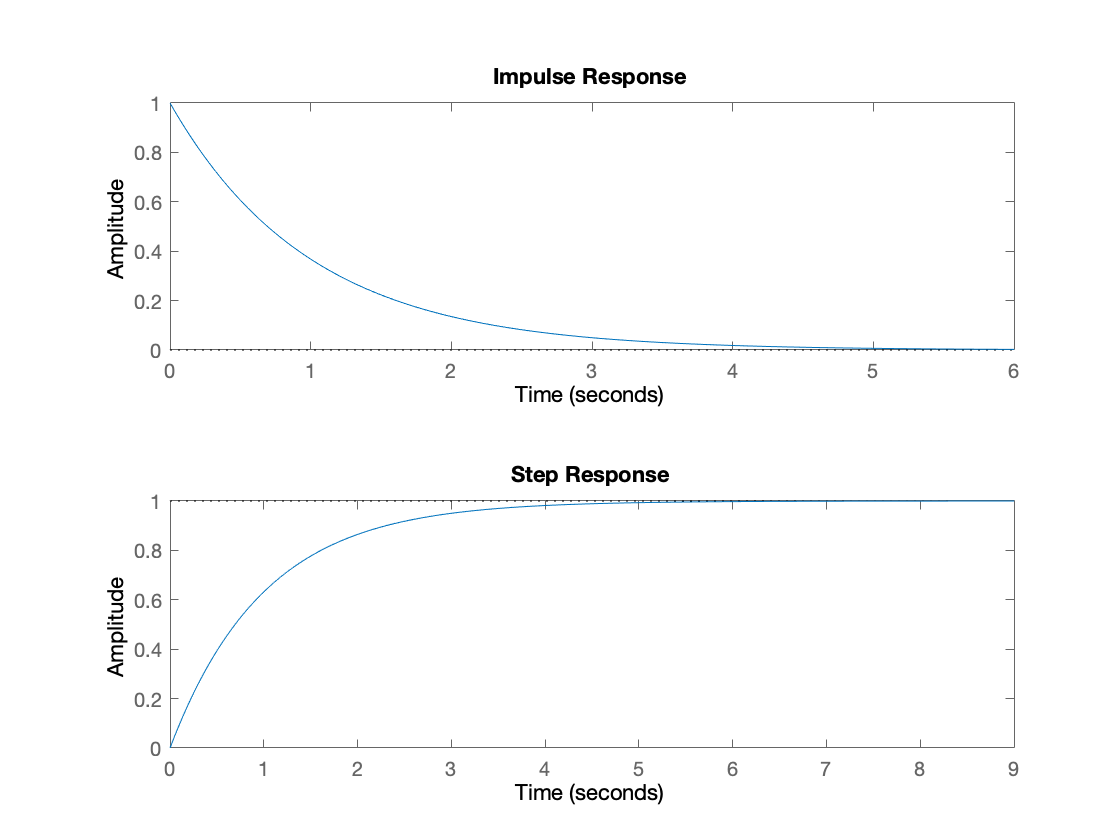

figure(1)
subplot(2,1,1); impulse(G1)
subplot(2,1,2); step(G1)

## Analise dos pólos e zeros

D = G1.denominator;

D =  cell2mat(D);

raizes = roots(D)  % pólos do sistema

raizes = -1

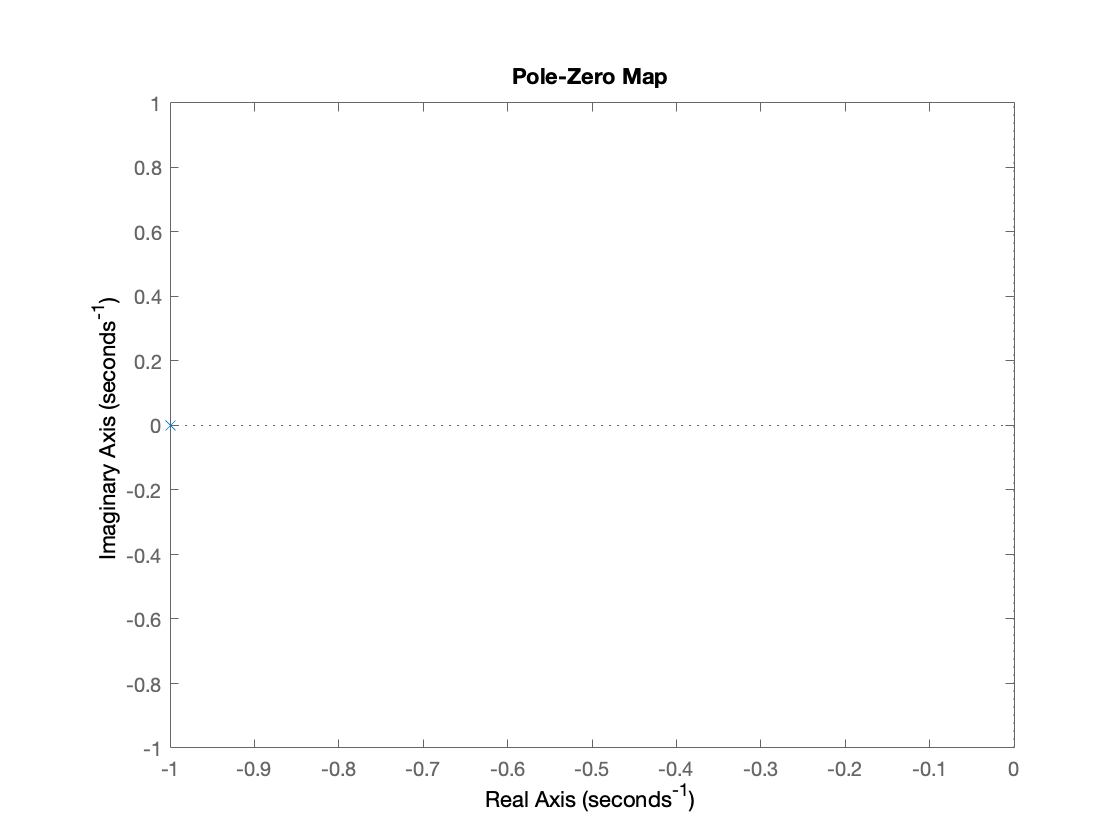

figure(2)

pzmap(G1)

## Resposta do sistema para uma entrada qualquer

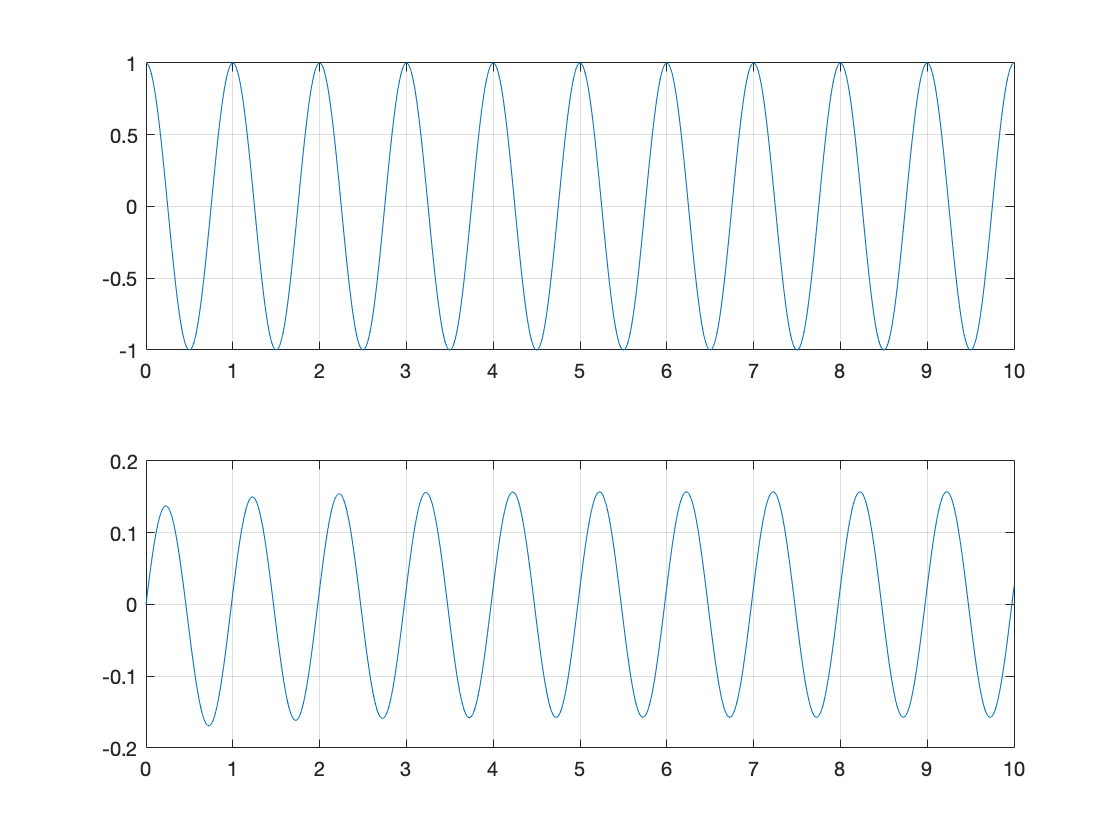


t = linspace(0,10,1000);
u = cos(2*pi*t);

y = lsim(G1,u,t);

figure(3)
subplot(2,1,1); plot(t,u);grid;
subplot(2,1,2); plot(t,y);grid;